# NOISE ANALYSIS

## Noise configuration

FIgure 3 shows the LTC6228 in a typical configuration. This will be the configuration used in this report to calculate noise

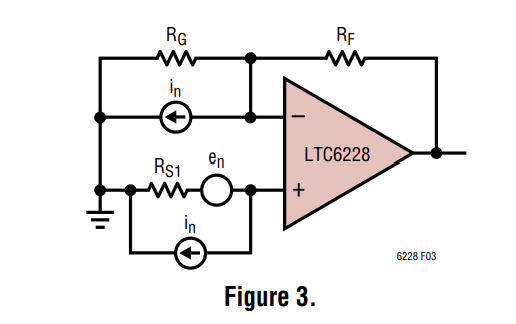

## Input noise in figure 3 can be calculated as: 

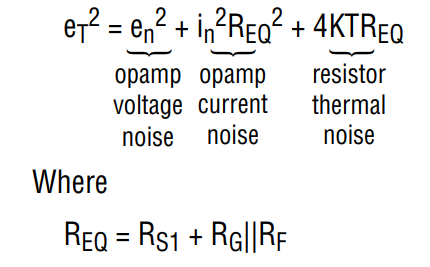

## Noise figure 

We will be evaluating the noise performance using NF and total output refered noise. Total output refered noise is used because it is easy to varify using simulation. 

We first define $\mathrm{SNR}=\frac{P_{\mathrm{signal}} }{P_{\mathrm{noise}} }=\frac{V_{\mathrm{signal}}^2 }{V_{\mathrm{noise}}^2 }=\frac{I_{\mathrm{signal}}^2 }{I_{\mathrm{noise}}^2 }$

Current noise figure:


$$\textrm{NF}=\frac{{\textrm{SNR}}_{\textrm{in}} }{{\textrm{SNR}}_{\textrm{out}} },\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\textrm{SNR}}_{\textrm{in}} =\frac{I_{\textrm{in}}^2 }{I_{n,\textrm{Rs}}^2 },\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\textrm{SNR}}_{\textrm{out}\;} =\left(I_{\textrm{in}}^{2\;} {A_i }^2 \right)/\left(I_{n,\textrm{Rs}}^2 {A_i }^2 +V_n^2 \right)\;$$



$$\mathrm{NF}=\frac{I_{\mathrm{in}\;}^{2\;} }{I_{n,\mathrm{Rs}}^2 }\frac{\left(I_{n,\mathrm{Rs}}^2 {A_i }^2 +V_n^2 \right)}{I_{\mathrm{in}}^2 {A_i }^2 }=1+\frac{V_n^2 }{I_{n,\mathrm{Rs}}^2 {A_i }^2 }$$


$I_{\textrm{in}}$: Input current signal of interest

$I_{n,\textrm{Rs}}^2$: input current noise comming from the source

$A_i$:  Transimpedance gain

$V_{n\;}^2$: output refered noise due to the amplifier witout input noise

We see that we can interpret NF as $1+\frac{\left(\textrm{output}\;\textrm{noise}\;\textrm{due}\;\textrm{to}\;\textrm{amplifier}\right)}{\textrm{output}\;\textrm{noise}\;\textrm{due}\;\textrm{to}\;\textrm{source}}$

Voltage noise figure:

Using a simular approach, we can find the voltage noise figure to be $\textrm{NF}=1+\frac{V_n^2 }{V_{n,\textrm{Rs}}^2 A^2 }$

$A_i$:  voltage voltage gain

## Noise calculation example (using LTC6229 opamp and RO7 parameters):

## Define some key parameters:

In=(6e-12)^2; % 6pA/sqrt(hz) current noise for ltc6229 @5Mhz
en=(0.88e-9)^2; % 0.88nV/sqrt(hz) voltage noise for ltc6229 @5Mhz
K=1.38*10^-23; % Botzmann constant
T=300; % room temperature in kelvin

Rs=5000; % the resistive part of the CMUT impdance in ohms
Co=100*10^-12; % the parasitic capacitance
wo=5*10^6; %frequency of operation @5Mhz



## 1. Noise analysis for voltage amplifier configuration

For this configuration, The amplifier is configured to have a gain of 20. This is equivalent to a total gain of 1 at 5Mhz due to the divider ration between Rs and Co

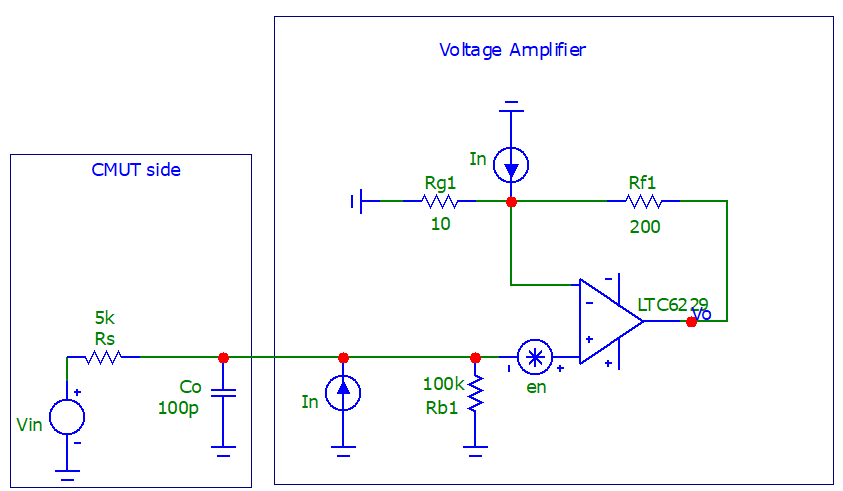

Rg1=10;  %
Rf1=200; % feedback resistor
Rb1=100000; % DC bias resistor
Zco1=1/(Co*2*pi*wo); % impedance of Co at frequency of operation

Av=(1+Rf1/Rg1); % the amplifier voltage gain
Vnr1=(4*K*T*Av^2)*(Zco1/(Zco1+(Rs*Rb1/(Rs+Rb1)))+Rg1)+4*K*T*Rf1 % output refered noise from Resistors. Unit in V^2/Hz

Vnr1 = 7.6799e-17

Vni1=((Rg1*Rf1/(Rg1+Rf1))+(Rs*Rb1)/(Rs+Rb1))*In*Av^2 % Opamp current noise in I^2/Hz

Vni1 = 7.5751e-17

Vnv1=(en*Av^2) %opamp voltage noise in V^2/Hz

Vnv1 = 3.4151e-16



NFv=1+(Vnr1+Vni1+Vnv1)/((4*K*T*Av^2)*(Rs*Rb1/(Rs+Rb1))*(Zco1/(Zco1+(Rs*Rb1/(Rs+Rb1))))^2) %opamp noise figure

NFv = 4.6188

Vnt=sqrt(Vnr1+Vni1+Vnv1) %total noise in V/sqrt(hz)

Vnt = 2.2227e-08

## Result analysis and simulation

From the above calculations, we obtained the following results:

NFv = 4.6188 (Noise figure)

Vnt= 22nV/sqrt(Hz) (Total output refered noise)

We simulated the system in LTspice and obtained a total output refered noise of 30nV/sqrt(Hz).

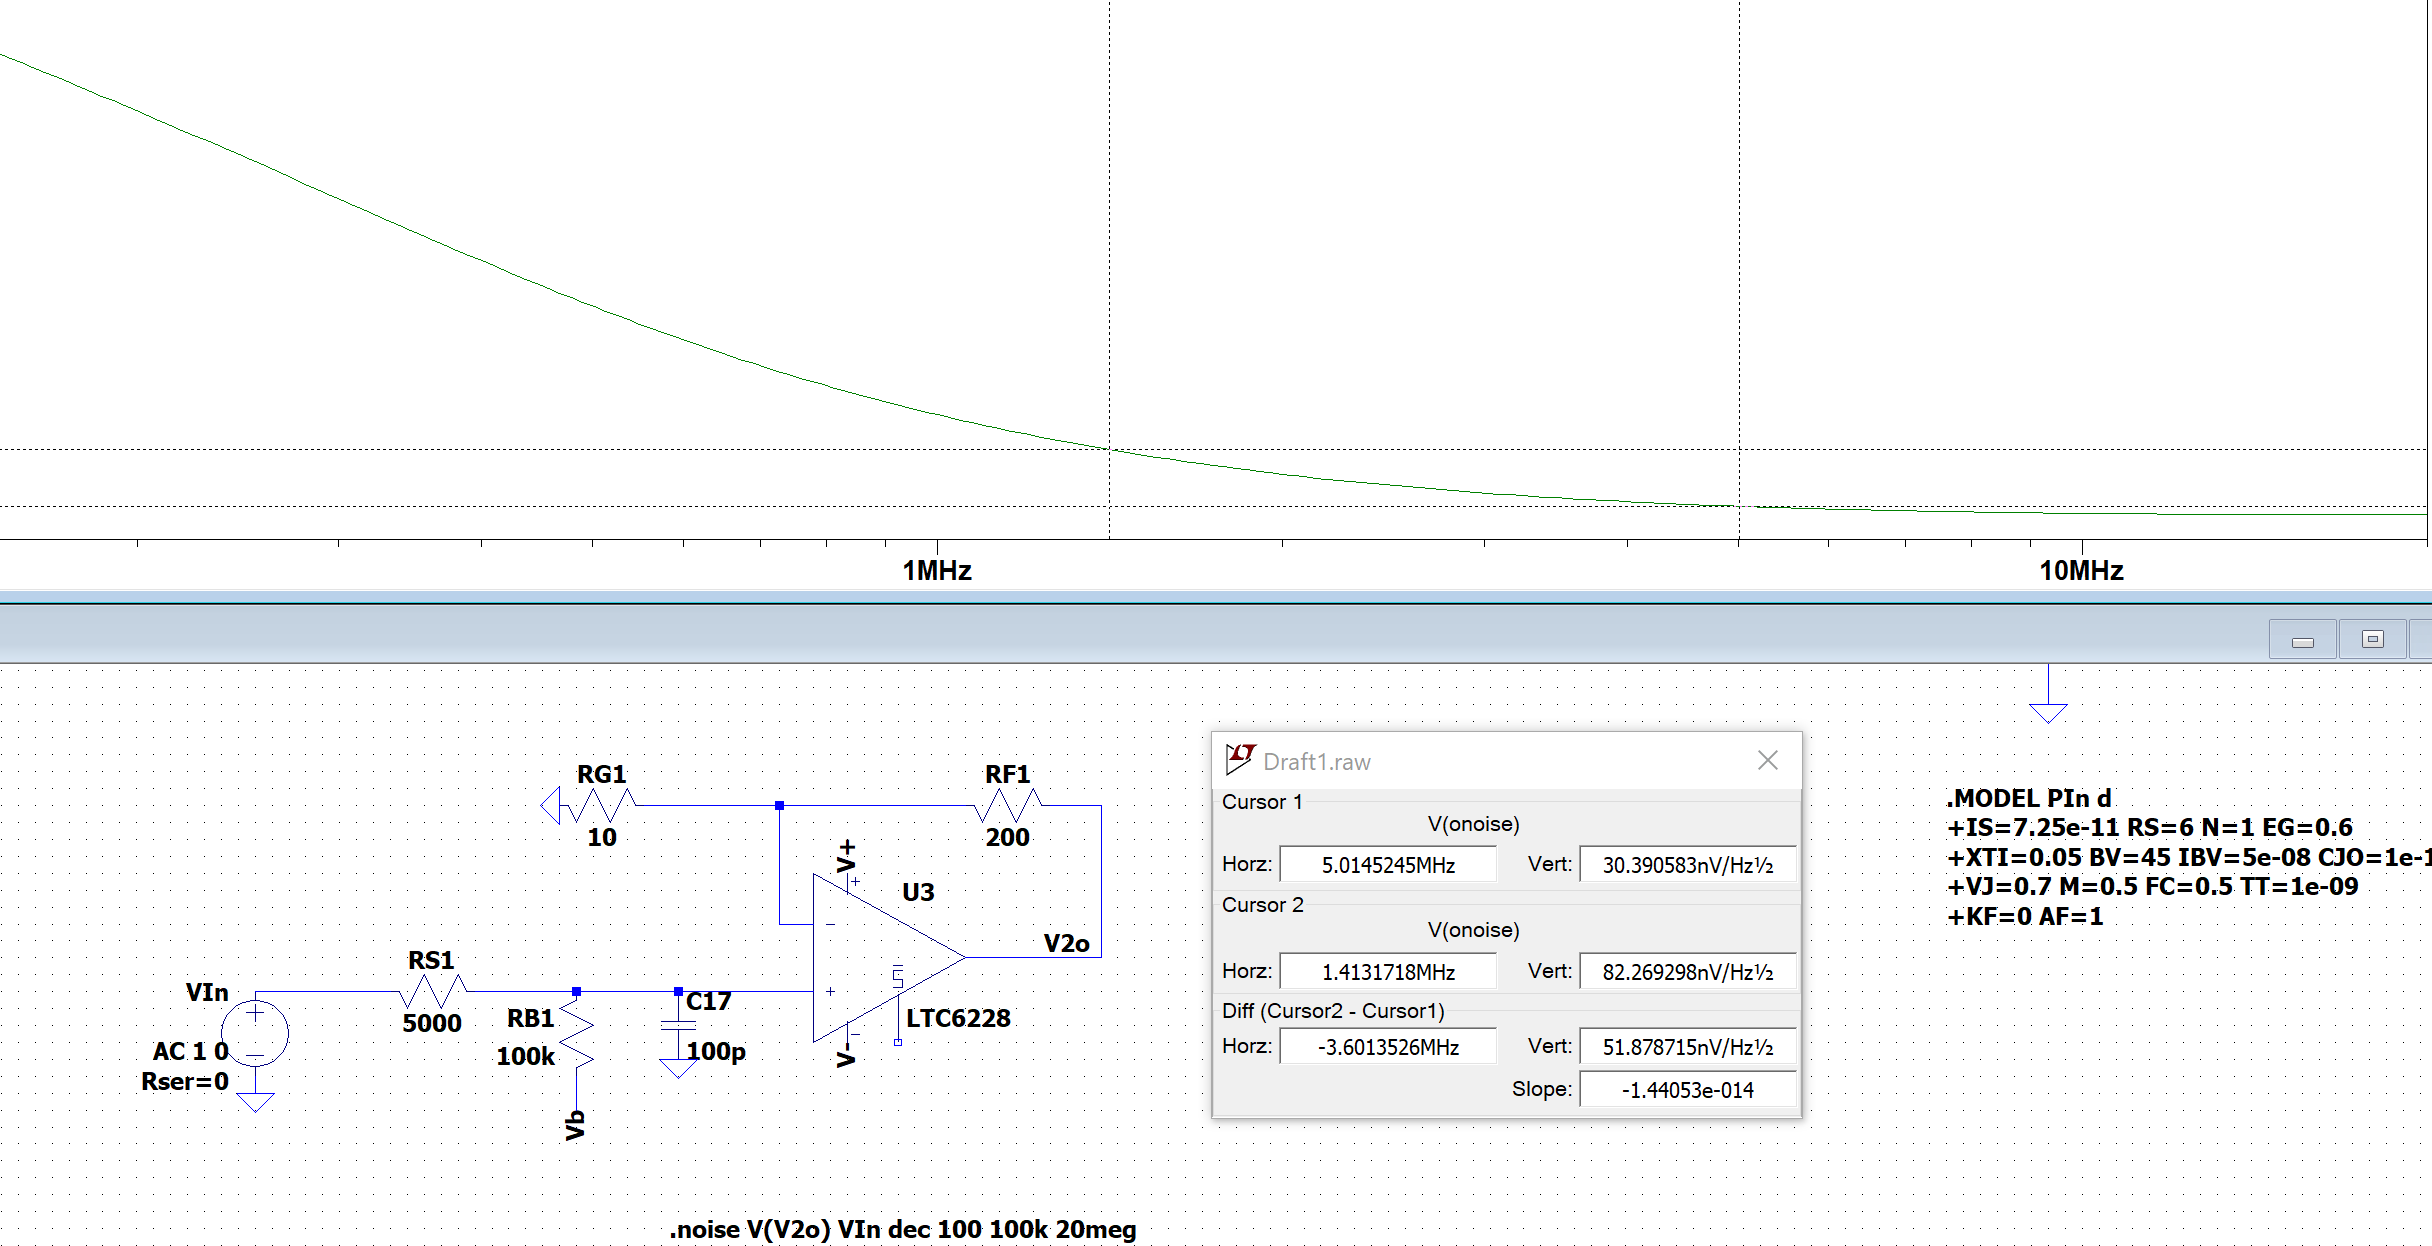

## 2. Noise analysis for current amplifier configuration

For this configuration, The amplifier is configured to have a gain of 10kohm. This is equivalent to a total voltage gain of 2 at 5Mhz.

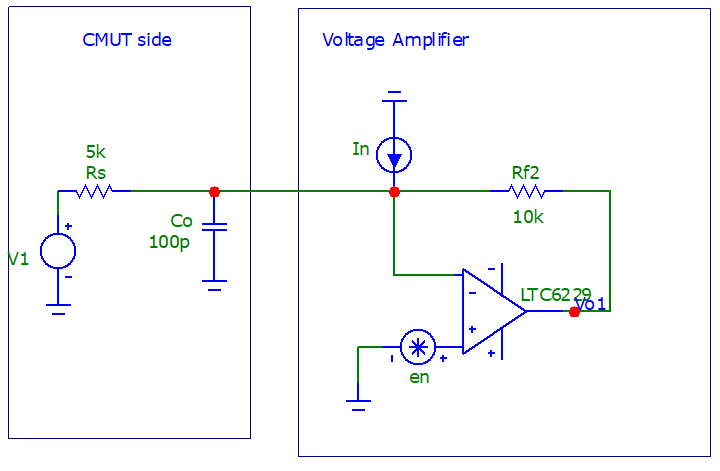

Rf2=10000; %feedback resistor
Zco2=1/(Co*2*pi*wo); % impedance of Co at frequency of operation

Ai=Rf2; % amplifier current gain
Av2=(1+Rf2/(Rs*Zco2/(Rs+Zco2)));
Vnr2=(4*K*T/Rs)*Rf2^2+(4*K*T*Rf2)% output refered noise from Resistors. Unit in V^2/Hz

Vnr2 = 4.9680e-16

Vni2=Rf2^2*In % Opamp current noise in I^2/Hz

Vni2 = 3.6000e-15

Vnv2=(en*Av2^2) %opamp voltage noise in V^2/Hz

Vnv2 = 9.1724e-16


NFv2=1+(Vnr2+Vni2+Vnv2)/(4*K*T/Rs*Rf2^2) %opamp noise figure

NFv2 = 16.1390

Vnt2=sqrt(Vnr2+Vni2+Vnv2) %total noise in V/sqrt(hz)

Vnt2 = 7.0810e-08

## Result analysis and simulation

From the above calculations, we obtained the following results:

NFv = 16.13 (Noise figure)

Vnt= 70nV/sqrt(Hz) (Total output refered noise)

We simulated the system in LTspice and obtained a total output refered noise of 48nV/sqrt(Hz).